#### Set up

load('amsr_n3125_Arctic_m03_y2025-v5.4.mat');
addpath("E:\University\EngSci Thesis\Thesis work\m_map");

month = month_ts(1);
day = 12;
year = year_ts(1);

#### Parameters

%% seaice concentration of the day to be studied 2D matrix
seaice = double(squeeze(seaice_ts(day,:,:)));

%% Define the polynya region of interest (ROI),
lat_min = 70; 
lat_max = 70.5;
lon_min = -24;
lon_max = -21;

%% Linear array of indices of the matrix cells that represents a point in polynya
polynya_roi = find(lat>=lat_min & lat<=lat_max & lon >= lon_min & lon <= lon_max);

#### Stereographic Projection of Sea Ice Concentration data

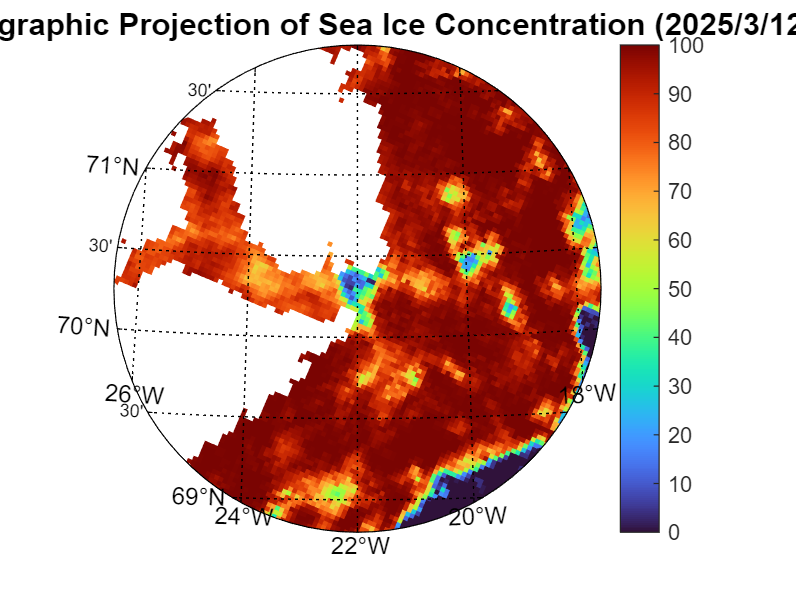

figure('Color','w');
hold on;

% Set up polar stereographic projection
m_proj('stereographic', 'lat', 70.3, 'long', -22, 'rad', 1.5);

% Overlay sea ice concentration
m_pcolor(lon, lat, seaice);
colormap("turbo");
clim([0 100]);
colorbar;
title_string = sprintf('Stereographic Projection of Sea Ice Concentration (%u/%u/%u)', year, month, day);
title(title_string, 'FontSize', 13);

% Add coastlines
% m_coast;    % The most basic coastline resolution is used
m_grid;

hold off;

#### Showing Polynya ROI

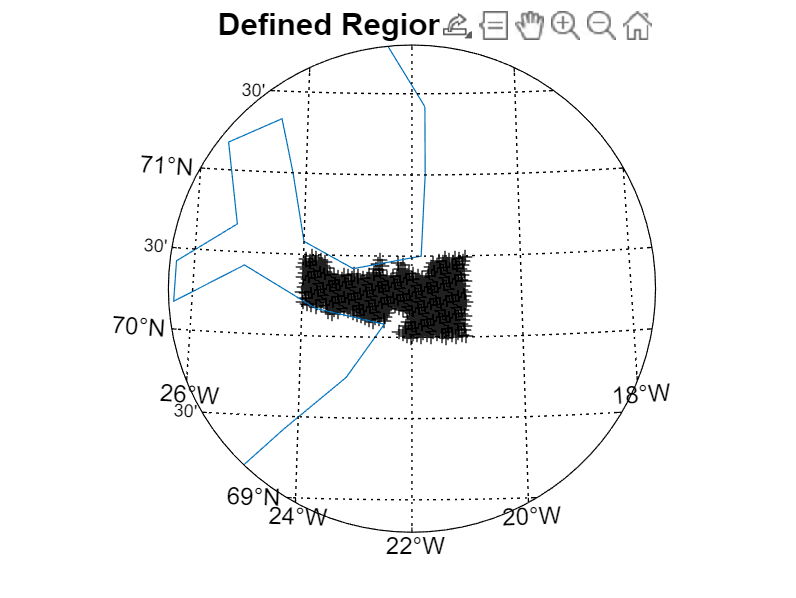

figure('Color','w');
hold on;

% Set up polar stereographic projection
m_proj('stereographic', 'lat', 70.3, 'long', -22, 'rad', 1.5);


%%%% Optional: Underlay sea ice concentration
% m_pcolor(lon, lat, squeeze(seaice_ts(day,:,:)));
% colormap("turbo");
% clim([0 100]);
% colorbar;

%%%% Identify regions
for i = polynya_roi(:)'  % Loop through each point in polynya
    if ~isnan(seaice(i))        % plot the point, if it does not correspond to land
        m_plot(lon(i), lat(i), '+', 'Color', 'k');
    end
end
title('Defined Region of Interest', 'FontSize', 13);

% Add coastlines
m_coast;    % The most basic coastline resolution is used
m_grid;

hold off;

#### Calculating Area of Open Water

Area of open water per cell (AOW_i) = (100 - ice_concentration)/100 × 3.125 km²

%%%% 
% Initialize counter for area of open water
aow=0;
for i = polynya_roi(:)'  % Loop through each point in polynya
    if ~isnan(seaice(i))        % plot the point, if it does not correspond to land
        aow_i = 100-seaice(i))/100 * 3.125;
    end
end

    0.8606

    0.9726

    0.9481

    1.0025

    1.1264

    1.2046

    1.0673

    0.8624

    0.7444

    0.6500

    0.7960

    1.0131

    1.0511

    1.0203

    1.0515

    1.1952

    0.8117

    0.7270

    0.4005

    0.6392

    0.6929

    0.8292

    1.0725

    0.9801

    0.9067

    1.0263

    1.1453

    0.6853

    0.4755

    0.5680

    0.6333

    0.7853

    0.9081

    0.9256

    1.0077

    0.8314

    0.8164

    0.9357

    0.6283

    0.4537

    0.4642

    0.5922

    0.8496

    0.8819

    0.8611

    1.0462

    0.8771

    0.8287

    0.7472

    0.7055

    0.5562

    0.4914

    0.6939

    0.7810

    0.9836

    0.9207

    0.8222

    0.7588

    0.8189

    0.4587

    0.5746

    0.7360

    0.9504

    0.9984

    0.8555

    0.8342

    0.6801

    0.4865

    0.4414

    0.6093

    0.7363

    0.7619

    0.7533

    0.6915

    0.5825

    0.2930

    0.5203

    0.5327

    0.4705

    0.6308

    0.6301

    0.7693

    0.7244

    